# 802.11 Preamble Detection

In this lab, we build a simple preamble detector for the 802.11 Wireless LAN standard. In doing this lab, you will learn to:

- Construct 802.11 packets using the MATLAB WLAN toolbox

- Identify the preamble portions of the packet

- Implement a cyclic auto-correlation detector for the short training field (STF)

- Implement a matched filter detector for the long training field (LTF)

- Evaluate the performance of the detector in terms of missed detection and timing error

- Build a simple offline detector on the SDR

- Implement functions as MATLAB `system` objects

To perform this lab you will need to install MATLAB's excellent  [WLAN Toolbox](https://www.mathworks.com/products/wlan.html). NYU students can install this toolbox for free.

**File structure and submission  **To organize the simulation, I have provided several files for this lab:

- wlamPreamble.mlx: This file. The main script for the test.

- WLANTx.m: Class file for a WLAN transmitter

- WLANRx.m: Class file for a WLAN receiver

Also, I have provided the following files.  You do not need to update them.

- RandDelayChan.m: Class file for a WLAN channel

- TxFilt.m:  Class file for the upsampling TX 

- RxFilt.m:  Class file for the upsampling RX

You will need to complete all the TODO sections of all files. Run the wlanPreamble.mlx live script. Print the script to PDF.   Do not submit source code.  No other formats accepted.

## 802.11 Packet Structure

To make the lab simple, we will focus on the simplest 802.11 standard, the 802.11g version which was developed in 2003. Most of the later standards use a similar packet detection procedure, with additional hooks for directionality and MIMO. So understanding this basic WLAN packet structure is a good place to start. 

The structure of all the 802.11 packet format is described in the [WLAN Toolbox packet structure](https://www.mathworks.com/help/wlan/ug/wlan-packet-structure.html) page.   The format for the 802.11g packet is shown below.

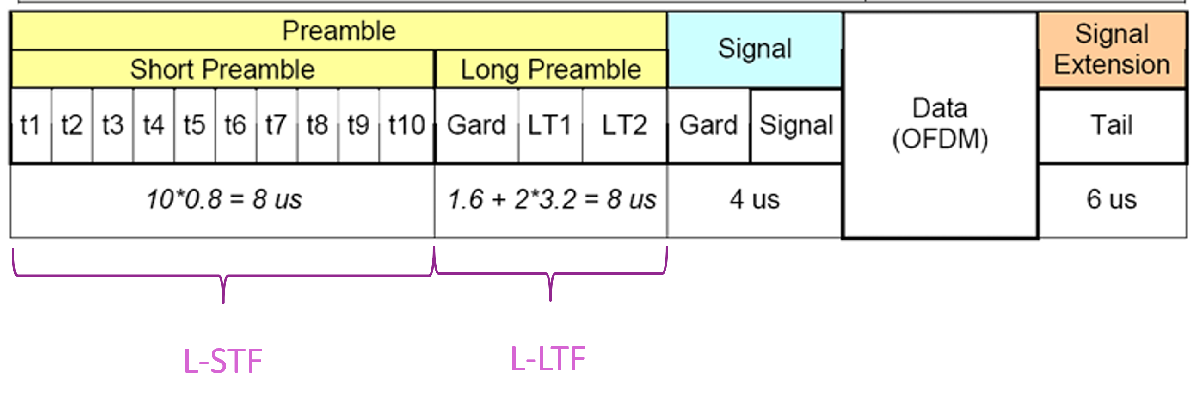

We focus on the first two fields in this lab:

- Legacy Short Training Field (LSTF): Used for AGC, packet detection and initial timing estimation. This is 8 us long.

- Legacy Long Training Field (LLTF): Used for fine timing estimation and initial channel estimation. This is also 8 us long. We will only look at fine timing estimation here.  We will look at channel estimation in the next lab.

## Generate and Visualize an 802.11g Packet

We first generate an 802.11 packet with random bits. The WLAN toolbox provides routines for creating WLAN packets with various configurations.  In this lab, we will implement all the functions as [MATLAB `system` objects](https://www.mathworks.com/help/matlab/matlab_prog/what-are-system-objects.html).  System objects are designed for dataflow type operations and are ideal for simulating communication systems.  In this lab, each function in the dataflow --  packet generation, TX upsampling, RX downsampling, and packet detection -- are realized as one system object.  We begin with the `WLANTx` object for the packet generation.  Complete the code in the contructor of `WLANTx` and in the  `stepImpl()` method. 

%  TODO:  Complete the code in the constructor and stepImpl() method in
%  WLANTx

% Once you are completed, run the following code which will
% generate an instance of the TX object and generate a packet.
wlantx = WLANTx('psduLen', 512);
x = wlantx();  % This calls the stepImpl() method.

% TODO:  Get the sample rate from wlantx.fsamp
%    fsamp = ...


% TODO:  Plot the absolute values of the samples in x vs. time in us.  If you did everything
% correctly, you should see that the packet is about 250 us long. 

Since the RX will have to detect the preamble, it needs to compute the preamble components.  This computation is performed in the method `WLANRx.compPreamble()`. 

% TODO:  Complete the code in WLANRx.compPreamble.


% Then, create an WLANRx() object, wlanrx, with the following command:
wlanrx = WLANRx();


After running the above command, the preambles should be stored in `wlanrx.lstf` and `wlan.lltf`.  :

- Compute and print the duration of each field in us (you can compute each field length with `length` command and use the sample rate).  You should get that both of them are 8 us.

- Re-do the plot with the `abs(x)` vs. time from above and place vertical lines at the end of the L-STF and L-LTF.

% TODO: Compute and print duration of each field
%   tstf = ...
%   tlft = ...


## Upsample and Scale TX Signal for a Desired Backoff

The SDR requires that we send it data at an over-sampled rate.  We will use the class `TxFilt` that was developed in the previous labs.  You do not need to modify this function, we just have to set the parameters.

For the TX filter,  set the following parmeters:

- Use an oversampling ratio `ovRatio=2`.   

- Set the filter passband, `Fp` to half the signal bandwdith, `sigBW`.  The signal bandwdith is based on the number of occupied sub-carriers in OFDM.  You do not have to understand this now.  We will explain later when we discuss OFDM.

- Set the filter stopband, `Fst, `reject the image that will be in frequencies `f >= fsamp/2`

Run the code below and then plot the frequency response using the `freqz` function. Label your axes. 

Run the following code to upsample and scale the signal for the backoff.. The code produces an output `xup` and a energy per sample, `Etx`. 

% Compute the signal bandwidth
info = wlanNonHTOFDMInfo('NonHT-Data');
sigBW = (max(info.ActiveFFTIndices)-min(info.ActiveFFTIndices)+1)/info.FFTLength*fsamp;

% Oversampling ratio
ovRatio = 2;

% Set the filter backoff level as in the previous lab
backoffLev = 9; 

% TODO:  Set the filter parameters
%   Fp = ...    % Filter passband
%   Fst = ...   % Filter stopband 


% Construct the TX filter object
txFilt = TxFilt('rateIn', fsamp, 'Fp', Fp, 'Fst', Fst, 'ovRatio', ovRatio, 'backoffAutoScale', true, 'backoffLev', backoffLev);


% Upsample the output
xup = txFilt(x);

% Get the upsampled rate 
fsampUp = txFilt.rateOut;

% Get the TX filter coefficients
b = txFilt.bfilt;

% TODO:  Use freqz to plot the frequency response of the filter in dB



% Get the average energy per sample in the packet
Etx = mean(abs(xup).^2);

## Pass the data through a channel with delay and noise

Before we run the signal through the SDR, we will use the class `WLANChan` to simulate a random delay. This class is already completed for you. You do not need to modify it. Right now, we will use it to simulate a fixed delay.

% Channel parameters
dlyRange = [50,100]*1e-6;   % Min and max of the delay in us
gain = 0;                   % channel gain in dB
snr = 20;                   % channel SNR in dB
wvar = Etx*db2pow(-snr);    % channel noise variance
nsampOut = 2^14;            % number of samples of output

% Create the channel 
chan = RandDelayChan('dlyRange', dlyRange, 'fsamp', fsampUp,...
    'gain', gain, 'wvar', wvar, 'nsampOut', nsampOut);

% Run the channel
[rup,dly] = chan(xup);

% Get the true delay in us
dlyus = dly*1e6;

The above code will output the channel output, `rup`, at the up-sampled frequency,  It also outputs the true delay, `dly` (in seconds) that was used.  We can use this true value to test the detection.  To visualize the delay, plot `abs(rup`)` vs. time in us.  Also, indicate the true delay in micro-seconds, `dlyus,` with a vertical line.  You should see that the true delay, `dlyus`, aligns with the beginning of the packet.

% TODO:   plot abs(rup) vs. time.  Also, plot the delay, dlyus with  a vertical line.

## Downsample the Received Signal

Next, downsample the signal.  The class `RxFilt()` has already been built for you and you do not need to modify it.   Again, you just need to set the filter parameters.  You can use the same ones that you used for the TX filter.  Then, you can run the code which will save the  downsampled received signal is stored in `r`.

% TODO:  Set the passband and stopband frequencies as before
%   Fp = ...
%   Fst = ...

% Construct the RX filter
rxFilt = RxFilt('ovRatio', ovRatio, 'rateIn', fsampUp, 'Fp', Fp, 'Fst', Fst, 'rxScale',false);

% Down-sample and scale the receive signal
r = rxFilt(rup);

## Detect the STF

WiFi preamble detection often works in two parts:

- Detect the STF via a cyclic correlation and find an approximate start of the packet, if detected

- If the STF is detected, we use a MF to precise locate the packet start

The STF is periodic with `x(n) = x(n+period)` for `period=16.`   It is also `len=160` samples long.  To detect such a sequence, we correlate the signal with a shifted version of itself. The squared correlation coefficient for a delay `i` will be denoted by `rhoSTF(i)` and can be computed from the following procedure:

The term `tol` is a small value to avoid division by zero.  

In MATLAB, these computations can be implemented without a for-loop.  For example, we can compute 

Similar instructions can be used for `rsq` and `rsqAvg` from which we can compute `rhoSTF`.  Complete the code in the `WLANrx.detectSTF()` method`:`

- Compute the correlation `rhoSTF `

- Find the maximum value obj.`rhoMax` 

- Set `pktFound = 1` if `obj.rhoMax > obj.tSTF` where `obj.tSTF` is a threshold.  We will use a value `obj.tSTF=0.25` which ensures a very low false alarm rate

- Set `obj.istf=imax, `the index `i` that maximizes `obj.rhoSTF.`  This value is an estimate of the beginning of the packet.

% TODO:  Complete the code in WLANRx.detectSTF() as above

Once you have completed that code, run the code below.  You should get that the `wlanrx.rhoSTF` is in the range `[0,1] `with a value near 1 at the peak.  Also, the peak of `rhoSTF` should match the true delay, `dlyus`. 


% Create an instance of the RX
wlanrx = WLANRx();

% Run the STF detector
wlanrx.detectSTF(r);

% TODO:  Plot the correlation wlanrx.rhoSTF vs. time in us.  Also, plot the
% location of the detected maximum



## Correlate with the long LTF

After detecting the STF, the RX typically searches for the LTF in a viciniy of the detected LTF.       Specifically, we first select a subset of the received vector `r` given by:

where the interval `i1:i2` contains the peak of the `STF` correlation.  Then, we run a match filter to compute the correlation coefficient of the LTF, `lltf`,  with the vector `r1`:

The value `tol` is a small value to prevent division by zero.  The above computations can be performed efficiently with the MATLAB `conv` function.  Complete the code `WLANRx.pktDetect() `and then run the code below to detect the packet beginning.

% TODO:  Complete the in WLANRx.pktDetect() to compute the correlation and peak detection with the L-LTF.  
% Test it with the following code.

% Create simulation objects
wlanrx = WLANRx();


% Perform the LTF correlation
wlanrx.pktDetect(r);


Plot the LTF correlation in `wlanrx.rhoLTF.  `You will see that there is a sharp peak with two other smaller peaks.  The smaller peaks are due to the fact that the LTF is repeated.

% TODO:  Plot the LTF correlation in rx.rhoLTF.  

## Measure the detection performance in noise

We now measure the detection performance in noise. complete the following code. The code should loop over the snrs in `snrTest`. For each snr, it performs `ntest=100` trials. In each trial, a random pacsadket is generated and sent over a random delay.  We then:

- Measure the missed detection rate, `pmd(i), `at each SNR = `snrTest(i)`.  

- Find the estimated and true delay at each 

You should see that the missed probability is about:

% Parameters
ntest = 100;              % number of points per SNR
snrTest = [-6:2:4]';      % SNR values to test
nsnr = length(snrTest);

% Initialize arrays
dlyEst = zeros(ntest,nsnr);
snrEst = zeros(ntest,nsnr);
dlyTrue = zeros(ntest,nsnr);
pmd = zeros(nsnr,1);
nfound = zeros(nsnr,1);

% Create system objects
wlantx = WLANTx('psduLen', 512);
wlanrx = WLANRx('psduLen', 512);
txFilt = TxFilt('rateIn', fsamp, 'Fp', Fp, 'Fst', Fst, 'ovRatio', ovRatio, 'backoffAutoScale', true, 'backoffLev', backoffLev);
rxFilt = RxFilt('ovRatio', ovRatio, 'rateIn', fsampUp, 'Fp', Fp, 'Fst', Fst, 'rxScale',false);

for isnr = 1:nsnr
    % Construct the simulation objects
    snr = snrTest(isnr);   
    chan = RandDelayChan('dlyRange', dlyRange, 'fsamp', fsampUp,...
        'gain', gain, 'wvar', wvar, 'nsampOut', nsampOut);
    
    i = 0;
    for it = 1:ntest
        
        % TODO:  Generate a random packet using wlantx()
        %    x = ... 
        

        % TODO:   Upsample with the txFilt   
        %    xup = ...
        

        % Compute the noise variance
        Etx = mean(abs(xup).^2);
        wvar = Etx*db2pow(-snr);
        chan.wvar = wvar;


        % TODO:  Pass through a random single path channel using the
        % chan.randChan method
        %     [rup, dly] = chan(...)        

        % TODO:  Down-sample
        %    r = rxFilt(...);
        

        % Run detection with the rx.pktDetect method.  
        wlanrx.pktDetect(r);

        % If packet is found:
        if wlanrx.pktFound
            i = i + 1;  % Increment counter of number of packets found

            % TODO:  Store:
            %     dlyTrue(i,isnr) = true delay 
            %     dlyEst(i,isnr) = estimated delay based on rx.iltf
              
        end
    end
    
    % Set number of packets found
    nfound(isnr) = i;

    % TODO:  Set     
    %   pmd(isnr) = fraction of packets that were missed.  
    
    
    % Print results
    fprintf(1,"SNR=%7.2f MD=%12.4e \n", snr, pmd(isnr));
end

% TODO:  Plot the missed detection vs. SNR.  You should see that the missed
% detection is low once the SNR is about 2 dB.

## Calibrate and Plot the Delay Error

We want to compare `dlyTrue` with `dlyEst.  `First, there is a fixed offset due to processing delays and filtering.  We can find this offset from the difference in the mean values at the highest SNR:

% TODO:  Compute the delay offset
%    dlyOff = ...


% TODO:  Set dlyEstAdj = dlyEst + dlyOff, which is the adjusted delay
% estimate.




Complete the following code that creates a scatter plot of the true and estimated delays for the detected samples at two different SNR values.  You should see that the two align well.  Note that even at low SNRs the delay estimate is good since we have discarded packets that were not detected well.

% SNR values to plot are snr(Iplot(j))
Iplot = [3,5];
nplot = length(Iplot);
for iplot = 1:nplot
    subplot(1,nplot,iplot);
    isnr = Iplot(iplot);     
    n = nfound(isnr);

    % TODO:  Create a scatter plot of dlyTrue(:,isnr) vs. dlyEstAdj(:,isnr)
    % Label the axes
    
end

## Running the Detection on the SDR

We will now run the detection on the SDR.    We first set the parameters:

% TODO:  Set parameters
% Set to true for loopback, else set to false
loopback = false;  

% Select to run TX and RX
runTx = true;
runRx = true;

% Flag indicating if pre-recorded data is to be used
usePreRecorded = false;
saveData = true;

We next create the system objects.  

% Compute the signal bandwidth
info = wlanNonHTOFDMInfo('NonHT-Data');
sigBW = (max(info.ActiveFFTIndices)-min(info.ActiveFFTIndices)+1)/info.FFTLength*fsamp;


% Intialize the communication objects
wlantx = WLANTx('psduLen', 512);
wlanrx = WLANRx('psduLen', 512);
fsamp = wlantx.fsamp;
ovRatio = 2;
fsampUp = fsamp*ovRatio;
txFilt = TxFilt('rateIn', fsamp, 'Fp', Fp, 'Fst', Fst, 'ovRatio', ovRatio, 'backoffAutoScale', true, ...
    'backoffLev', backoffLev);
rxFilt = RxFilt('ovRatio', ovRatio, 'rateIn', fsampUp, 'Fp', Fp, 'Fst', Fst, 'rxScale', true);


% TODO:  Generate a random packet using wlantx()
%    x = ... 


% TODO:   Upsample with the txFilt   
%    xup = ...


% Set the packet length
wlanrx.set('pktLen', length(x));


Create the SDR objects.

% clear previous instances
clear devtx devrx

% add path to the common directory where the function is found
addpath('..\..\common');


% Set the parameters.  Note that we capture twice the number of samples
% to ensure that we always have a full packet in the window
nsampsFrameTx = length(xup);
nsampsFrameRx = 2*length(xup);
centerFrequency = 2.4e9;

% Run the creation function.  Skip this if we are using pre-recorded
% samples
if ~usePreRecorded
    [devtx, devrx] = plutoCreateTxRx(createTx = runTx, createRx = runRx, loopback = loopback, ...
        nsampsFrameTx = nsampsFrameTx, nsampsFrameRx=nsampsFrameRx, sampleRate = fsampUp, ...
        centerFrequency=centerFrequency);
  
end

Continuously transmit the upsampled TX data, `xup` 

if runTx
    % TODO:  Use the devtx.release() and devtx.transmitRepeat() commands to
    % continuously send xup
  
end


We will try to capture one packet.


if usePreRecorded  
    load singData;
else
    % TODO:  Capture data at the upsampled rate.  Capture nsampsFrameRx.
    %   rup = rx.capture(...)    
end
if saveData
    save singData rup;
end


% TODO:  Down-sample
%   r = rxFilt(...);

% TODO:  Run detection with the rx.pktDetect method.  


% TODO:  Plot wlanrx.rhoSTF vs. time in us


## Running a Continuous Monitor

Complete the code below to run the code in a continuous monitor.  You should see that the location of the RX samples jumps around.  This is because the RX timing is each interval is at an arbitrary point relative to the TX timing.  You may also occassionally get a low correlation when the pre-amble arrives at the end of the search window.

% Number of iterations
nit = 100;

% Initialize arrays to store data
rhoMax = zeros(nit,1);                  
rxTime = zeros(nit,1);

% Initialize plots
clf;
subplot(1,2,1);
rhoMaxToNow = [0,0];
timeToNow = [0,3];
prhoMax = plot(timeToNow,rhoMaxToNow, 'o-', 'LineWidth', 2);
ylim([0,1]);
xlabel('Time [sec]');
ylabel('rhoMax');
grid on;

subplot(1,2,2);
n = length(wlanrx.rhoSTF);
trho = (0:n-1)/fsamp*1e6;
rhoSTF = wlanrx.rhoSTF;
prho = plot(trho, rhoSTF);
ylim([0,1]);
xlabel('Time [us]');
ylabel('rho');
grid on;


% Set pointers to X and Y data for both plots
prhoMax.XDataSource = 'timeToNow';
prhoMax.YDataSource = 'rhoMaxToNow';
prho.XDataSource = 'trho';
prho.YDataSource = 'rhoSTF';

% Initialize array to save data
measData = zeros(nsampsFrameRx, nit);

% Load pre-recorded data if need
if usePreRecorded
    load multData;
    
end

for it = 1:nit
    
  
    if usePreRecorded
        rup = measData(:,it);

    else
        % TODO:  Get the data
        %  rup = devrx.capture(...)
        

        % Get the time
        if (it==1)
            tic;
        end    
        rxTime(it) = toc();
    end
    if saveData
        measData(:,it) = rup;
    end
      
    

    % TODO:  Down-sample
    %   r = rxFilt(...);
    
    
    % TODO:  Run detection with the wlanrx.pktDetect method.  
    

    
    % Get the STF correlation and create the vectors to plot
    n = length(wlanrx.rhoSTF);
    trho = (0:n-1)/fsamp*1e6;
    rhoSTF = wlanrx.rhoSTF;

    % TODO:  Get the maximum correlation
    %   rhoMax(it) = ...    
   
     
    % Update the plots   
    timeToNow = rxTime(1:it);
    rhoMaxToNow = rhoMax(1:it);    
    refreshdata;
    drawnow;

end

% Save the data
if saveData
    save multData measData rxTime;
end